# EEE3548 Exercise #1

## [2020142010] [유미진]

#### Q1. Map the real part of $e^{j2\pi(f_xx+f_yy)}$ over the range of -50 to 50 for both x and y. Try using $f_x = f_y = 0.02$.    

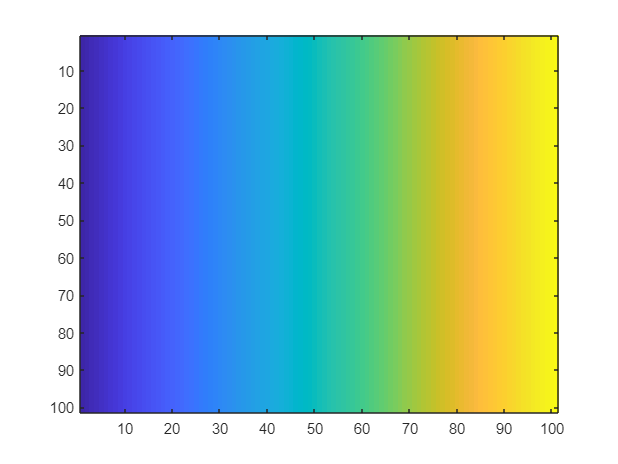

x=-50:50; % -50부터 50까지 101개의 정수 생성
y=-50:50;

[X,Y]=meshgrid(x,y); % 101*101 matrix 생성

figure(); imagesc(X); %행렬이니까 imagesc로 plot

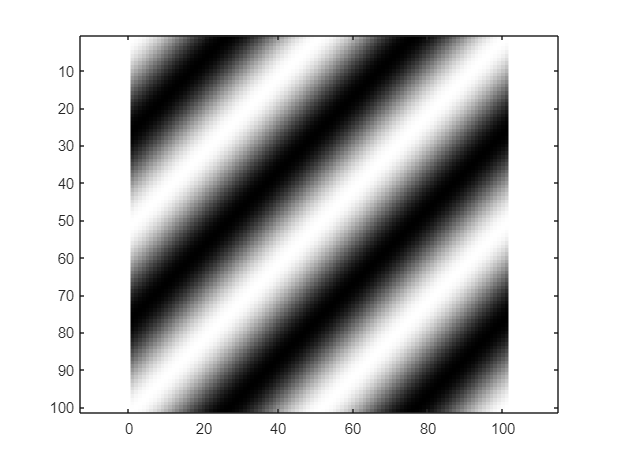

kx=0.02;
ky=0.02;
img = exp(1j*2*pi*(kx*X+ky*Y));
figure; imagesc(real(img));colormap gray; axis equal;

#### Q2. Test with different spatial frequency pairs. How would you flip / rotate the direction of the 2D sinusoid?

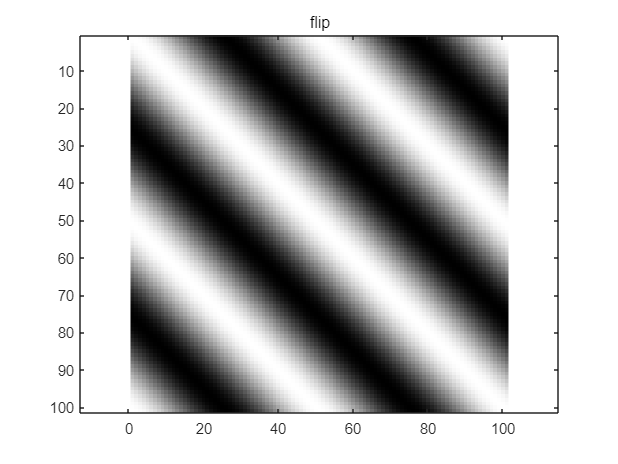

x=-50:50;
y=-50:50;

[X,Y]=meshgrid(x,y);

kx=0.02;
ky=0.02;
img = exp(1j*2*pi*(-kx*X+ky*Y)); % x, y값중 하나(x)의 부호를 바꿈
figure; imagesc(real(img));colormap gray; axis equal;
title('flip');

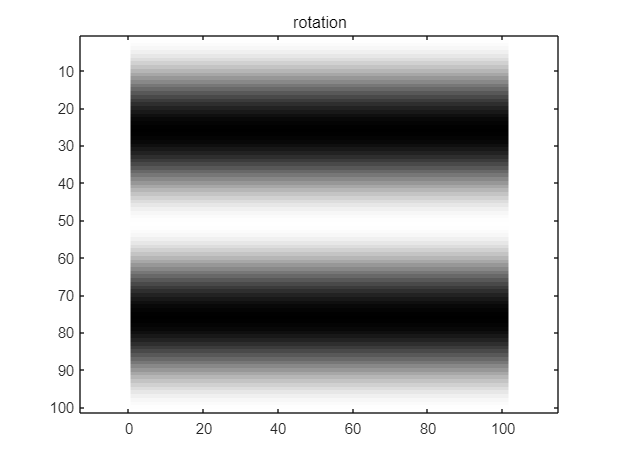

img = exp(1j*2*pi*(0*X+ky*Y));% x, y값중 하나(x)를 0으로 만듦
figure; imagesc(real(img));colormap gray; axis equal;
title('rotation');

#### Q3. Defind a function that performs 1D DFT in matrix-vector mutiplication for a given 1D input. (at the end of the file)

g=rand(10,1)

g =     0.2760
    0.6797
    0.6551
    0.1626
    0.1190
    0.4984
    0.9597
    0.3404
    0.5853
    0.2238


A = DFT(g)

A =    4.5000 + 0.0000i
  -0.1362 + 0.3289i
  -0.0235 - 1.3787i
  -0.7647 + 0.3026i
  -0.2906 - 0.5267i
   0.6903 + 0.0000i
  -0.2906 + 0.5267i
  -0.7647 - 0.3026i
  -0.0235 + 1.3787i
  -0.1362 - 0.3289i


B = fft(g)

B =    4.5000 + 0.0000i
  -0.1362 + 0.3289i
  -0.0235 - 1.3787i
  -0.7647 + 0.3026i
  -0.2906 - 0.5267i
   0.6903 + 0.0000i
  -0.2906 + 0.5267i
  -0.7647 - 0.3026i
  -0.0235 + 1.3787i
  -0.1362 - 0.3289i


#### Q4. Compare the speed with the built-in fft function. Try different input sizes.

tic
DFT(g)

ans =    4.5000 + 0.0000i
  -0.1362 + 0.3289i
  -0.0235 - 1.3787i
  -0.7647 + 0.3026i
  -0.2906 - 0.5267i
   0.6903 + 0.0000i
  -0.2906 + 0.5267i
  -0.7647 - 0.3026i
  -0.0235 + 1.3787i
  -0.1362 - 0.3289i


toc

경과 시간은 0.012129초입니다.


tic
fft(g)

ans =    4.5000 + 0.0000i
  -0.1362 + 0.3289i
  -0.0235 - 1.3787i
  -0.7647 + 0.3026i
  -0.2906 - 0.5267i
   0.6903 + 0.0000i
  -0.2906 + 0.5267i
  -0.7647 - 0.3026i
  -0.0235 + 1.3787i
  -0.1362 - 0.3289i


toc

경과 시간은 0.005831초입니다.


#### Q5. Perform 2D FFT using fft2() and plot the magnitude spectrum. 

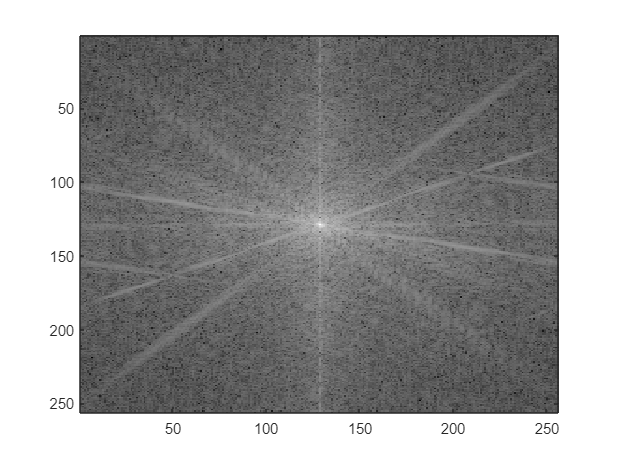

img = imread('cameraman.tif');
fimg = fftshift(fft2(img)); % shift 꼭 해야 함. 순서도 fft 하고 나서 fftshift 해야함
figure;imagesc(log(abs(fimg)));colormap gray %magnutude 얻으려고 abs 취했고, 변화가 눈에 잘 띄게 하려고 log까지 취함

#### Q6. Define 2D sinusoidal images as in Q1 in the spatial frequency domain. Take IFT and take abs to visualize it. How can you define the spatial frequencies/directions of the sinusoidal pattern? How would you shift the phase of the sinusoid?

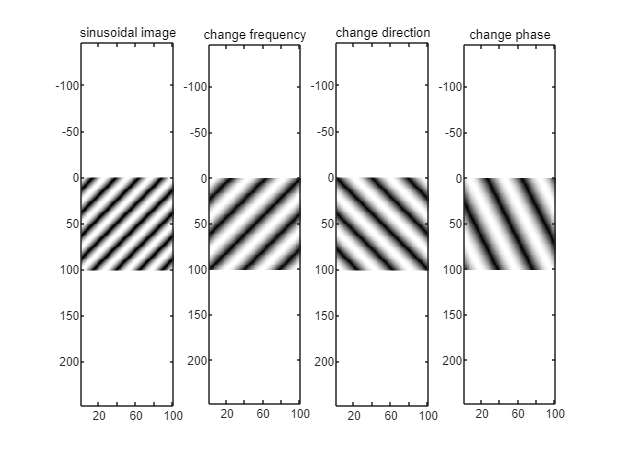

x=-50:50;
y=-50:50;

[X,Y]=meshgrid(x,y);
kx=0.02;
ky=0.02;
img = fftshift(fft2(exp(1j*2*pi*(kx*X+ky*Y))));
img_spatial = ifft2(ifftshift(img));
figure;
subplot(1,4,1); imagesc(abs(real(img_spatial))); colormap gray; axis equal; title('sinusoidal image'); %real로 봐도 sinosoidal이고 imag로 봐도 sinosoidal임
subplot(1,4,2);
kx=0.013; % change the frequencies
ky=0.013;
img = fftshift(fft2(exp(1j*2*pi*(kx*X+ky*Y))));
img_spatial = ifft2(ifftshift(img));
imagesc(abs(imag(img_spatial))); colormap gray; axis equal; title('change frequency');
subplot(1,4,3);
img = fftshift(fft2(exp(1j*2*pi*(kx*X-ky*Y)))); % change the directions (ky -> -ky)
img_spatial = ifft2(ifftshift(img));
imagesc(abs(imag(img_spatial))); colormap gray; axis equal; title('change direction'); % imag로 허수부 출력

subplot(1,4,4);
img = fftshift(fft2(exp(1j*2*pi*(kx*X-ky/2*Y)))); % change the phase (change the ky -> ky/2)
img_spatial = ifft2(ifftshift(img));
imagesc(abs(imag(img_spatial))); colormap gray; axis equal; title('change phase'); % imag로 허수부 출력

#### **Q7. Based on the lecture, perform ****2D Linear convolution**** between the cameraman.tif and 2D gaussian function with **$\sigma$ **= 30. You can use built-in function for 2D gaussian.**

#### **(a) Check the FT of the 2D gaussian function**

#### **(b) Generate 2D Linear convolution using FFT (you may pad zeros to the edge of the images)**

#### **(c) Check the result both the frequency and spatial domain. Discuss the Results**

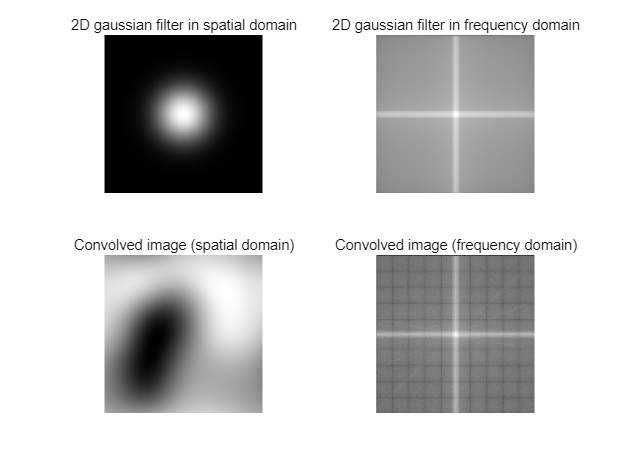

g1=Gaussian_filter(250,30);


figure;
subplot(2,2,1);
imshow(g1, []);
title('2D gaussian filter in spatial domain'); %gaussian filter 그냥 plot

img = imread('cameraman.tif');

% Convert the image to double for computation
img = im2double(img);

% Pad the image and the filter
padded_img = padarray(img, [5,5] , 0 , 'both'); %테두리 5칸을 0으로 padding
padded_g1 = padarray(g1, [5,5] , 0, 'both');

result_fft = fft2(padded_img, size(padded_g1,1),size(padded_g1,2)) .* fft2(padded_g1); %fft 한 거 끼리 곱함!! -> 즉 G임
% Perform 2D linear convolution using FFT
result = ifftshift(ifft2(result_fft)); %그러고 다시 ifft하면 결과를 spatial domain에서 확인!! 즉 g임!!

subplot(2,2,2);
imshow(log(abs(fftshift(fft2(g1)))), []) %gaussian fft 한 거를 frequency domain에서 확인
title('2D gaussian filter in frequency domain');

subplot(2,2,3);
imshow(abs(result), []); % 결과를 spatial domain에서 확인
title('Convolved image (spatial domain)');


subplot(2,2,4);
imshow(log(abs(fftshift(result_fft))), []); % 결과를 frequency domain에서 확인. imshow(log(abs(fftshift(fft2(result)))), []);로 해도 됨
title('Convolved image (frequency domain)');

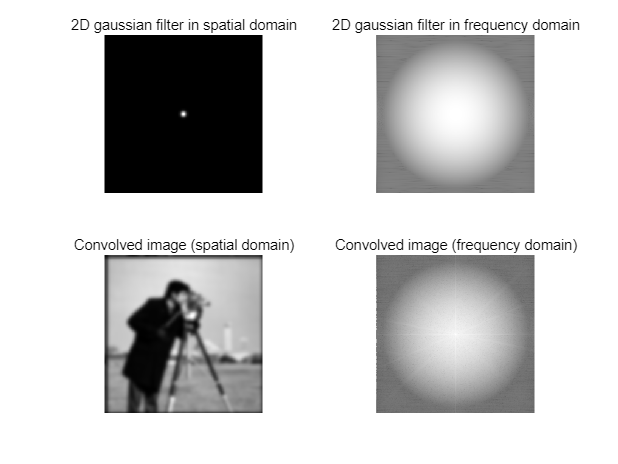

g2=Gaussian_filter(250,3);


figure;
subplot(2,2,1);
imshow(g2, []);
title('2D gaussian filter in spatial domain'); %gaussian filter 그냥 plot

img = imread('cameraman.tif');

% Convert the image to double for computation
img = im2double(img);

% Pad the image and the filter
padded_img = padarray(img, [5,5] , 0 , 'both'); %테두리 5칸을 0으로 padding
padded_g2 = padarray(g2, [5,5] , 0, 'both');

result_fft2 = fft2(padded_img, size(padded_g2,1),size(padded_g2,2)) .* fft2(padded_g2);
% Perform 2D linear convolution using FFT

subplot(2,2,2);
imshow(log(abs(fftshift(fft2(g2)))), []) %gaussian fft 한 거를 frequency domain에서 확인
title('2D gaussian filter in frequency domain');

result2 = ifftshift(ifft2(result_fft2));
subplot(2,2,3);
imshow(abs(result2), []); % 결과를 spatial domain에서 확인
title('Convolved image (spatial domain)');


subplot(2,2,4);
imshow(log(abs(fftshift(result_fft2))), []); % 결과를 frequency domain에서 확인. imshow(log(abs(fftshift(fft2(result)))), []);로 해도 됨
title('Convolved image (frequency domain)');

## Function

function G = DFT(g)
    M = length(g);
    W = exp(-1j*2*pi/M*(0:M-1)'*(0:M-1));
    
    G = W*g;
end